## PHYS 434 Lab 3

Kuan-Wei Lee

Student#:1663855

Lab Partner: Megan Miyasaki

## Problem 1

In our first example we are looking at the temperature reading (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12 Kelvin to within the 0.4 degree precision of the thermometry and the thermal control system (standard deviation). However, there are times when the thermal control system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and we just had a wonky reading, in an abundance of caution we want to throw those values out too.

To make this a bit concrete, we will simulate a little data. Start by simulating 100k 'good' data points assuming Gaussian fluctations, and because we are playing god adding the following 'bad' datapoints: {10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7}

A) So our goal is to identify bad data and throw it out.

- Start by exploring the data you have created with appropriate plots

- State the statistical question in words. Be very clear, and describe why you have chosen this statistical question.

- Restate your question in math. Be very clear.

- Apply your statistical test and construct a truth table.

**True****False**

Pos

Neg

The idea is how often you kept the known good data (True Pos), how often you correctly discarded bad data (False Neg), and how often mistakes were made of either omission or commission (True Neg, & False Pos).

B) How does the number of omissions, where you threw out good data, depend on the statistical threshold you chose and is it a predictable quantity?

C) Are there mistakes of commission (bad data getting in)? If yes, are they avoidable and how do they depend on your statistical threshold?

------------------------------------------------------------------------------------------------------------------------------------------------------------------

**A.**

The temperature reading of an experiment is mostly within 0.4K range around 12K. Here we assume that the temperature data has Gaussian fluctuation with mean = 12K and standard deviation = 0.4K.

I will use the matlab function "random" to generate 100k Gaussian distributed temperature data with mean = 12, 

sigma = 0.4.

After the data is made, I will add bad data points to the original data I made and plot it with a histogram to show that the data does have Gaussian distribution

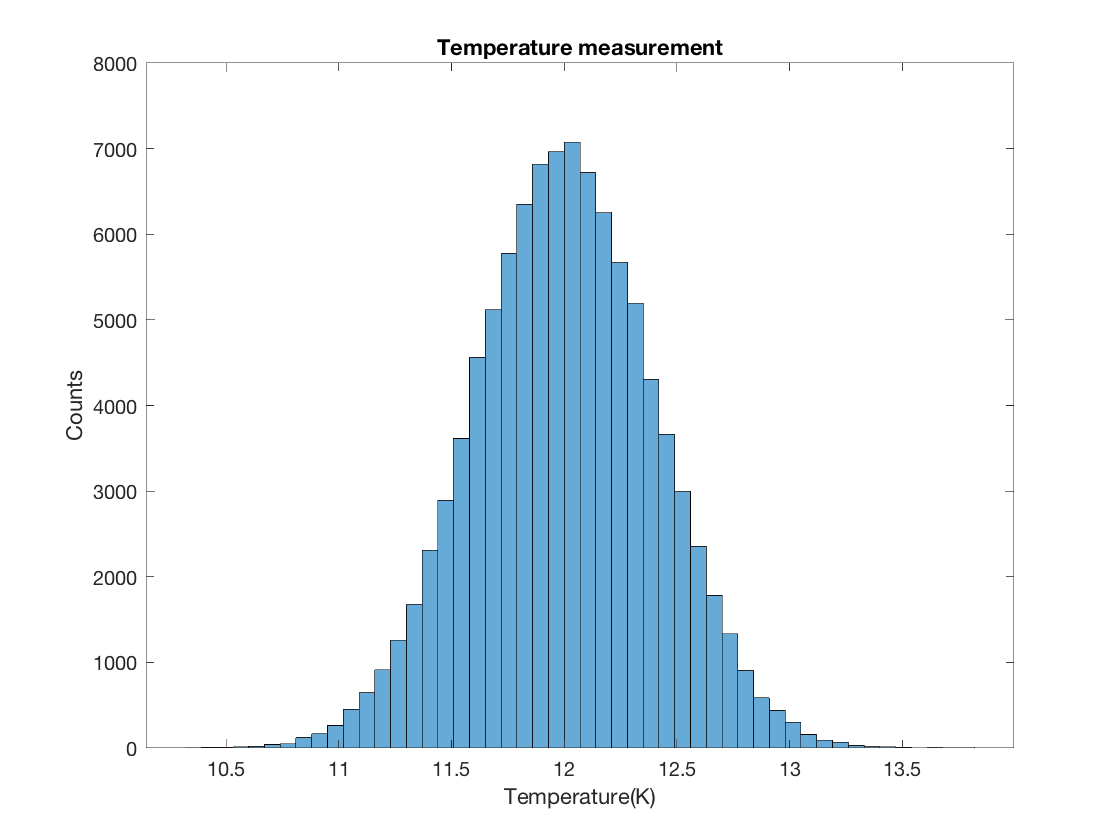

clear all
close all
clc

Temp = random('Normal',12,0.4,1,100000);
histogram(Temp,50)
title('Temperature measurement')
xlabel('Temperature(K)')
ylabel('Counts')

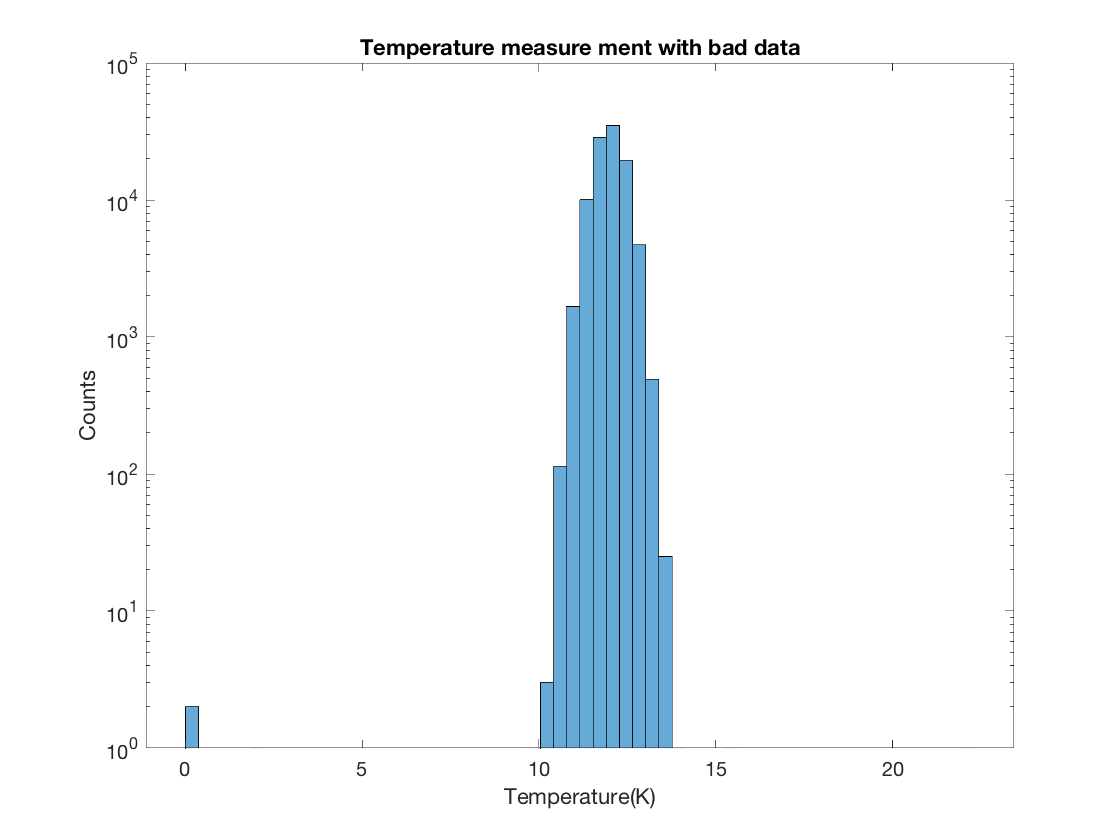

bad_data = [10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7];
Temp_new = [Temp bad_data];
histogram(Temp_new,60)
set(gca,'YScale','log')
title('Temperature measure ment with bad data')
xlabel('Temperature(K)')
ylabel('Counts')

In this context, we assume that we know the values of all the 100K good data points and the values of 8 bad data points. We decide the threshold that seperates "good data" from "bad data". Here I set the treshold to be 5 sigma. The temperature associates with 5 sigma is 10K and 14K. Any temperature that is below 10K or beyond 14K will be throw away.

The statistical quesiton that I am trying to answer is:

If we treat the temperature measurements that are beyond 5 sigma range(Temperature$<10K,$Temperature$>14K$) as "bad data points", what is the probability of keeping a data that we think is good and it is actually good, what is the probability of keeping a data that we thinks is good but it is actually bad? what is the throwing away a data that we think is bad but is actually good, and what is the probability of throwing away a data that we think is bad and it is actually bad?

Since we know the data that we throw away is the data beyond the 5 sigma range, we know the probability of a good data point situating beyond 5 sigma range is $2*1/3\ldotp 5*{10}^{-6}$.(Prob. of a good data being $\pm 5\;\textrm{sigma}\;$ away from the mean)  We also know that we have 100K good data and 8 bad data in our data set. The probability of picking out a data that is a "good data" is 100000/100008. The probability of picking out a data that is "bad data" is : 8/100008. Assume that we know the values of all 8 data points. The probability of a "bad data" situating beyond  5 sigma range is 5/8(There are 5 bad data points situate beyond 5 sigma range and there are 8 bad data points in total). The probability of a "bad data" situating with in 5 sigma range is 3/8.(There are 3 bad data situate within 5 sigma range).

With all these information, we can calculate the probability of 4 scenarios: 

- Probability of keeping a data that we think is good and it is actually good **(True Pos)**

- Probability of keeping a data that we think is good but it is actually bad **(True Neg)**

- Probability of throwing away a data that we think is bad but is actually good **(False Pos)**

- Probability of throwing away a data that we think is bad and it is actually bad **(False Neg)**

Probability of scenario 1 is : (Prob. of picking out a good data )* (Prob. of good data being within 5 sigma range)= 100000/100008*[1-(2/$3\ldotp 5*{10}^{-6}$)]

Probability of scenario 2 is : (Prob. of picking out a bad data )* (Prob. of good data being within 5 sigma range)= (8/100008)*(3/8)

Probability of scenario 3 is : (Prob. of picking out a good data )* (Prob. of good data being beyond within 5 sigma range) = (100000/100008)*(2/$3\ldotp 5*{10}^{-6}$)

Probability of scenario 3 is : (Prob. of picking out a bad data )* (Prob. of bad data being beyond within 5 sigma range) = (8/100008)*(5/8)

After setting up the mathematical equation for the probability, I then use matlab codes to calculate the probability.

Prob_5sigma = 1-normcdf(5,0,1);
Prob_good = 100000/100008;
Prob_bad = 8/100008;
Prob_5sigmabad = 3/8;

Prob_scen1 = Prob_good*(1-2*Prob_5sigma);
Prob_scen2 = Prob_bad*(1-Prob_5sigmabad);
Prob_scen3 = Prob_good*2*Prob_5sigma;
Prob_scen4 = Prob_bad*Prob_5sigmabad;

The table below is the truth table that I made based on the probability calculated.

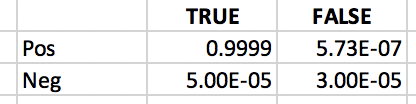

This truth table will provide us some important information such as, when we throw away a data point, what is the probability of it being a good data and when we keep a data point what is the probability of it being a bad data. Again, these probability is calculated based on the assumption that we know what the good data points and bad data points are. In the real situation, we will not have those information. Hoever, we could figure some ways to test the stability of the measurement and estimate how often does the measurement glitch. A possible way to identify a bad data point is when a given measurement is very far away from the previouse ones where  a good amounts of measurements are stabily situate around the same value. (If we expect the temperature to be stable and does not fluctuate violently). Note that the truth table I constructed was in the form of probability. It yeilds some interesting information that are usefule in some situations such as when you want to figure out the probability of throwing away a good data when you decide to throw away a data point. It also tells you the possiblility of keeping a bad data when you decide to keep a data point. I will approach the same problem in a different perspective and method in the later section.

B.

If the threshold is lowered(for example, from 5 sigma to 3 sigma), the amount of good data that is thrown away will increase because there are more good data situation beyond 3 sigma than the amounts of good data situation beyond 5 sigma.  The amount of good data thrown away is predictable with the threshold that we set if the good data has Gaussian distribution. Because we know that we have 100K good data and 8 bad data. If we find the amount of good data situating beyond the threshold, we will know how many good data points we threw away. (This is based on the assumption that we know what are the values associated with good data and bad data)

C.

There are certain amounts of false comissions because some bad data have values that are lower than the threshold.Lowering the threshold(for example, from 5 sigma to 3 sigma) , will allows less bad data to be kept because bad data tend to have higher measurements. Setting the threshold closer to the mean will make sure that less bad data is kept. However, setting the threshold closer to the average means that more good data are thrown away. Therefore, making the threshold very high or very low are both undesirable because we either throw away too many good data or keep too many bad data.

Previously in section A, I asked a statistical question and end up constructed a truth table in terms of probability. Here I am going to ask the statistical question in a different way. In the end, I should get a truth table in the form of numbers of data points. First of all, the assumption is the same. We know what data points are good and what are bad. The interesting question is: If we treat all the data points that situate beyond 3 sigma range(Temp>13.2K||Temp<10.8K) as bad data and throw them away, how many good data points will I throw away and how many bad data points will I keep?(Assume we know that we have 100K good data and 8 bad data). Since we know what data points are good and what are bad, we can look at all the good data points and count how many good data points are beyond the threshold. We can also look at all the bad data points and count how many bad data points are within the threshold.

Since we have 100008 data points, we are not actually looking at them one by one and pick out the values manually. Instead, I will write a matlab code to do it efficiently. The code that picks out amounts of good data points that situate beyond 3 sigma range and picks out amounts of bad data points situating within 3 sigma range is as following:

(Quick note, the reason for setting threshold to 3 sigma is that there is no good data points situating beyond 5 sigma range. Setting the threshold lower to 3 sigma will make sure that we throw away good data by mistake)

%pick out the temperature that is higher than 13.2K and lower than 10.8K
%from good data
ind1 = Temp>13.2;
ind2 = Temp<10.8;
high = Temp(ind1);
low = Temp(ind2);
FalsePos = length(high)+length(low);
TruePos = 100000-FalsePos;
ind1 = bad_data>13.2;
ind2 = bad_data<10.8;
high_b = bad_data(ind1);
low_b = bad_data(ind2);
FalseNeg = length(high_b)+length(low_b);
TrueNeg = length(bad_data)-FalseNeg;

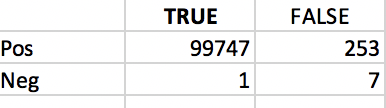

In the end, we found that by setting the threshold to 3 sigma, we threw away 253 good data out of 100000 good data and kept 1 bad data out of 8 good data. These numbers were calculated based on the assumption that we know what are good data points and what are bad data points. Therefore, I am not sure how usefule this result is when we are dealing with a real system where we don't know which measurements are good which are bad. In my personal opinion, the probability version of the truth table yields more usefule information. The probability version of truth table can always be obtained if we can estimate how often does the glitch happens(for example, how many glitches we usually get in 100000 measurements and how far away from the mean are they normally situate). With the estimation of the frequency and the location of glitches, we can then formulate a truth table by asking: when we decide to throw out a data point, what is the probability of it being a good/bad data point? when we decide to keep a data point, what is the probability of it being a good/bad data point?

**Problem 2 **

In this example we will be looking for asteroids. If we look at the alignment of stars on subsequent images, they don't perfectly align due to atmospheric and instrumental effects (even ignoring proper motion). The resulting distribution is two dimensional, and for this lab let's assume it is a 2D Gaussian with 1 arcsecond RMS.

If I have a potential asteroid, it will have some true movement between the images. We would like a '5 sigma' detection of movement. What is that distance in arcseconds?Or said another way, if I histogram how far all the (stationary) stars appear to have moved I get something like:

- What is the question in words?

- What is the question in math?

[Hint: Come up with an analytic description of your pdf(). The Blue Book may be helpful here.]

----------------------------------------------------------------------------------------------------------------------------------------------

Since the image of stationary stars have some shifts due to atmospheric and instrumental effect, the movement of the image we detect might be caused by the background noise rather than the real movements of the celestial bodies. To claim that the real movements of the asteroid is observed, the amounts of displacement has to have a significance of 5 sigma. 

The statistical question that we will try to answer is then: How big does an observed displacement have to be to make the probability of the observed displacement equal to or greater than the observed displacement from the background noise smaller than 5 sigma (1/3.5*10^6)?

The mathametic calculation we need to do to answer the question is:


$$\int_X^{\infty } P\left(x\right)\textrm{dx}=1/3\ldotp 5*{10}^6 ,\textrm{Find}\;\textrm{vlaue}\;X\;\textrm{that}\;\textrm{satisfy}\;\textrm{this}\;\textrm{equation}$$


The random shifting of the image (background noise) is a 2D Gaussian distribution with 1 arcsecond RMS.

To make our evaluation of probability easier, let's change the 2D Gaussian distribution into a 1D distribution. The 2D Gaussian distribution is made by the displacement in x direction and displacement in y direction, which are both Gaussian distributed. If we want to know the displacement in a polar coordinates where the radial displacements in polar coordinates are defined as($r^2 =\sqrt{{\Delta x}^2 +{\Delta y}^2 }$). The distribution of the radial distribution :$X_r =\sqrt{X_1^2 +X_2^2 },\textrm{where}\;X_1 \;\textrm{is}\;\textrm{the}\;\textrm{distribution}\;\textrm{of}\;\textrm{the}\;x\;\textrm{displacement},\textrm{and}\;X_2 \;\textrm{is}\;\textrm{the}\;\textrm{distribution}\;\textrm{of}\;y\;\textrm{displacement}\ldotp$

Since both X1 and X2 are Gaussian distribution with mean = 0 and sigma =1, Xr will be a Rayleigh distribution. To find the distribution Xr, I will first find the RMS(root mean square) of X1 and X2. Finding the 5 sigma detection of movement requires integrating the probability distribution function of the Rayleigh distribution made up by the RMS of X1 X2. To find the data point that is associate with 5 sigma probability with "icdf" in matlab, we need to identify the type of distribution we are integrating and the parameters of the distribution. We already know that the distribution function we are integrating is a Rayleigh distribution. If we can find the standard deviation of the Rayleigh distribution, we can than find the data point that is associate with the 5 sigma probability.

To find the standard deviation of Rayleigh distribution, we can start with the fact that the expectation value(mean) of the Rayleigh distribution is related to the standard deviation by the formula: $E\left\lbrack x\right\rbrack =\sigma \sqrt{\pi /2}$. After we find the mean of the Rayleigh distribution, the standard deviation can be found. 

The mean of Rayleigh distribution can be found by the integral: $\int_0^{\infty } x*x/\sigma^2 *\exp \left(-x^2 /2\sigma^2 \right)\textrm{dx}$

However, the data we have here is not a continuous function. Instead, we have a vectors that contain probabilities associated with the displacement values.

Finding the mean then become the summation: $\sum_{i=1}^N x_{i*P_i } /\sum_i^N P_i$

The code below will calculate the Rayleigh distribution by finding the RMS of $\Delta x$ distribution and $\Delta y$ distribution, and then calculate the mean and sigma of the Rayleigh distribution. After the sigma of Rayleigh distribution is found, the data point associated with 5 sigma probability will be found with "icdf". 

clear all
close all
clc

%Both X and Y displacement are Gaussian distributed with mu = 1 sigma = 1 and range from -3 to 3.
mu = 0;
sigma = 1;
x = -3:0.1:3;
y = -3:0.1:3;
delt_x = pdf('Normal',x,mu,sigma);
delt_y = pdf('Normal',y,mu,sigma);
Rayleigh = sqrt(delt_x.^2+delt_y.^2);
x_ray = linspace(0,9,length(x));
plot(x_ray,Rayleigh)
title('Distribution of raidial displacement')
mu_ray = sum(x_ray.*Rayleigh)/sum(Rayleigh);
sigma_ray = mu_ray/sqrt(pi/2);
%5 sigma raidial displacement
X = icdf('Rayleigh',1-1/(3.5e6),sigma_ray);

The result of the matlab code suggests that the 5 sigma radial movement is 19.7106 arcsecond. It suggests that to claim the detection of an asteroid movement, the radial displcement of the image (RMS of delta x and delta y) has to be at least 19.7106 because the probability of the background giving a reading that is equal to or greater than 19.7106 arcsecond is 5 sigma (1/3.5*10^6).

**Problem 3**

As we discussed in class, one of the key backgrounds for gamma-ray telescopes are cosmic rays. Cosmic rays are charged particles—usually protons or electrons but can include atomic nuclei such a alpha particles (helium) or iron. Because of their charge cosmic rays spiral in the magnetic field of the galaxy. From the perspective of the Earth they appear to be coming uniformly from all directions like a high energy gas, and the direction the cosmic ray is travelling when it reaches the Earth tells us nothing about where it came from because we don't know what tortured path it has taken through the galaxy to reach us. However, at trillion electron volt energies and above, the spiral loops are fairly big and the sun and the moon will block cosmic rays. This means the sun and the moon appear as holes in the cosmic ray sky (cosmic rays from that direction are absorbed).

Assume a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute (arrivals are random in time). If we can observe where the moon is for 8 hours per night (not too close to the horizon) and we observe for 15 days and see 6800 cosmic rays, what is the signficance of our moon shadow detection?

As always:

- What is the question in words?

- Translate the question to math, describing both the expected background pdf() and the integral you need to do.

- Convert to sigma.

There are some unique aspects to this problem. Make sure you explore them in your explanation.

**-------------------------------------------------------------------------------------------------------------------------------------**

**3.**

If we are observing the sky where we normally have a cosmic ray rate of 1 cosmic ray per minute and there is a moon on the sky, we would expect that the cosmic ray rate we actually observe will be smaller than 1 cosmic ray per minute because some cosmic rays are obsorbed by the moon. The question is how big of an effect is the absorbtion of cosmic rays by the moon? To answer this question, we observe the sky where there is a moon for 8 hours per night over 15 days. We can find the distribution of the cosmic ray counts for 8 hours per night and over 15 days since we know the distribution of the cosmic ray counts over 1 minute period. To find the distribution of cosmic ray counts over 15 days, we need to convolve the distribution of cosmic ray counts in 1 minute period for 60*8*15 = 7200 times. (There are 60 minutes per hour and we observe for 8 hours per night over 15 days). The distibution of cosmic ray counts will be a discrete distribution because you can only get integer numbers of counts of cosmic ray. Here we assume that the distribution is a Poisson distribution with

 lambda = 1(The average rate of cosmic ray is 1 ray per minute). Convolving(in another words, summing) this distribution for 7200 times will give us the distribution of cosmic ray counts for 8 hours per night over 15 days. 

After observing the sky for 8 hours per night for 15 days, we see 6800 cosmic rays. To investigate how big of an effect is the moon shadowing, we can find the sigma of 6800 cosmic ray counts given that the background distribution is a Poisson distribution convolved 7200 times. In this context, finding sigma of 6800 cosmic ray counts means finding the probability of getting cosmic ray counts equal to or smaller than 6800 counts from measuring the background. The reason why we are interested in finding probability of getting cosmic ray counts lower than 6800 counts is because we want to know if 6800 counts is a number that is much lower than the number of counts we expect when there's no obsorbtion from the moon. If getting 6800 counts is a very unlikely event when there's no moon patch on the sky, it means that the obsorbtion of the cosmic rays by the moon is a very significant effect. On the other hand, if 6800 counts is not much lower than the counts we expect, it means that the obsorbtion by the moon is not a strong effect.

The statistical we have to answer to investigate the effect of moon obsorbtion is then:

What is the probability of observing 6800 cosmic rays from the background if we observe for 8 hours per night over 15 days given that the back ground distribution is a Gaussian? What is the sigma of this probability?

This question in mathematic form is:


$$P\left(6800\right)\int_{-\infty }^{6800} 1/\sqrt{2\pi \sigma^2 }\;\exp \left(-{\left(x-\mu \right)}^2 /2\sigma^2 \right)\textrm{dx}$$



$$1-P\left(6800\right)=\int_{-\infty }^X 1/\sqrt{2\pi \sigma^2 }\;\exp \left(-{\left(x-\mu \right)}^2 /2\sigma^2 \right)\textrm{dx}\;,\mu =0\;,\sigma =1\;\;$$



$$\textrm{solve}\;\textrm{for}\;X\ldotp X\;\textrm{will}\;\textrm{be}\;\textrm{the}\;\textrm{sigma}\;\textrm{of}\;P\left(6800\right)$$


You might notice that the background distribution is actually a Poisson distribution instead of a Gaussian distribution. However, after convolving the Poisson distribution for 7200 times, the Poisson distribution approaches to be a Gaussian distribution. Therefore, we can treat our backgraound distribution like a Gaussian. When a Poisson distribution with lambda = 1 is convolved for N times, the Poisson distribution will approaches to a Gaussina distribution with $\mu =N\lambda \;,\sigma =\sqrt{N\lambda }\;,\textrm{where}\;\lambda =1\;,\textrm{and}\;N\;\textrm{is}\;\textrm{large}$. In this context, N is 7200 and it is large enough.

Before I evaluate the integral I listed above, let me justify the choice of integrating from the left end (- infinity) instead of the right(+ infinity). Since we are investigating the significance of the moon obsorbtion effect, lower cosmic ray counts will be more "signal like". Therefore, integrating from the lower end is a more reasonable choice.

The matlab code below will first make a Gaussian distribution with mu = 7200, sigma = sqrt(7200) and then integrate the pdf from -infinity to 6800. (This action has been justified in the previous section.) After the probability is found, the sigma associated with the probability will be calculated.

clear all
close all
clc

mu = 7200;
sigma = sqrt(7200);
Gaussian = makedist('Normal',mu,sigma);
%Probability of measureing 6800 counts assuming background is a Gaussian 
P_6800 = cdf(Gaussian,6800);
%Sigma associated with the probability found above
X = icdf('Normal',1-P_6800,0,1)

X = 4.7140

In the end, the sigma associated with the probability of getting 6800 counts for 8 hours per night over 15 days is 4.7140. It is very close to 5 sigma but slightly lower. This suggests that the absorbtion effect of the moon is not ignorable. The obsorbtion of the cosmic rays by the moon certainly has some significance.